# Invariant Transformation of Upcroft

## What is it?

The Upcroft invariant transform is a method that generates images robust to variations in illumination, including shadows and intensity changes. The method is based on the logarithmic relationship between color channels and is used to improve the classification of urban scenes in changing environments.

## Basic operation of the transformation

**1. RGB spectral model:**

Although not explicitly stated in the paper, it is mentioned that the invariant transform method is based on the logarithmic relationship between RGB channels and references earlier work such as that of Ratnasingam and Collins. The spectral response of a specific channel $\rho_k$ (with 𝑘={𝑟,𝑔,𝑏}) is defined as:


$$\rho_k = \sigma \int E(\lambda) S(\lambda) Q_k(\lambda) d\lambda$$


where:

- $\sigma$: constant factor denoting Lambert shading.

- $E(\lambda)$: incident illumination on the perceived surface element.

- $S(\lambda)$: spectral reflectance of the surface.

- $Q(\lambda)$: $k$ channel spectral sensitivity.

- $\lambda$: wavelength.

**2. Logarithmic transformation:**

The invariant transformation uses the logarithmic relationship between the $RGB$ channels to minimize the variability caused by the geometry, intensity and spectrum of the light source.


$$F = \log(G) - \alpha \log(B) - (1 - \alpha) \log(R)$$


**3. Calculation of the **$\alpha$** parameter:**

The $\alpha$ parameter is calculated to minimize the variability of the light source. This is achieved by using the peak wavelengths of the sensors:


$$\frac{1}{\lambda_G} = \frac{\alpha}{\lambda_B} + \frac{1 - \alpha}{\lambda_R}$$


## Implementation analysis:

**1. Input parameters:**

- $RGB$: image in RGB format.

- $alpha$: parameter for logarithmic approximation.

**2. Separation of channels:**

First, the function saves each image channel, $R$, $G$ and $B$, separately.

R = double(RGB(:,:,1));
G = double(RGB(:,:,2));
B = double(RGB(:,:,3));

**3. Calculation of the **$\alpha$** parameter**

The $\alpha

$ parameter is canned in a separate function and passed as a parameter.

alpha = (lambda3 / (lambda3 - lambda1)) * (1/lambda2 - 1/lambda3);

**4. Invariant transformation:**

Finally, the function performs the invariant transformation with parameter $\alpha$:

I_Upcroft = log(G) - alpha*log(B) - (1 - alpha)*log(R);

### Complete code

function alpha = calcular_alpha(lambda1, lambda2, lambda3)
    alpha = (lambda3 / (lambda3 - lambda1)) * (1/lambda2 - 1/lambda3);
end

function I_Upcroft = upcroft_transform(RGB, alpha)
    % Separation of the RGB image by double channels
    R = double(RGB(:,:,1));
    G = double(RGB(:,:,2));
    B = double(RGB(:,:,3));
    
    % Invariant transformation
    I_Upcroft = log(G) - alpha*log(B) - (1 - alpha)*log(R);
end

An example of a program image and its corresponding transformation:

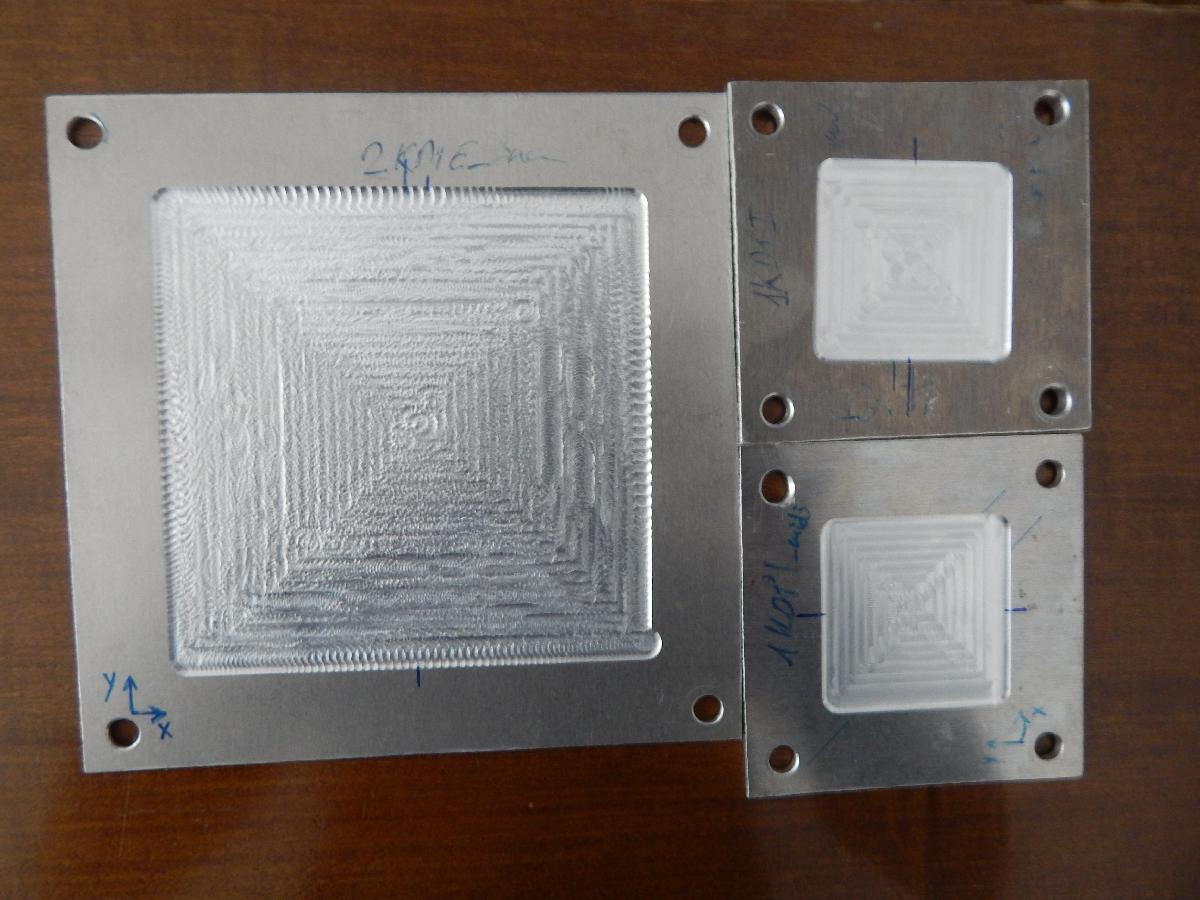    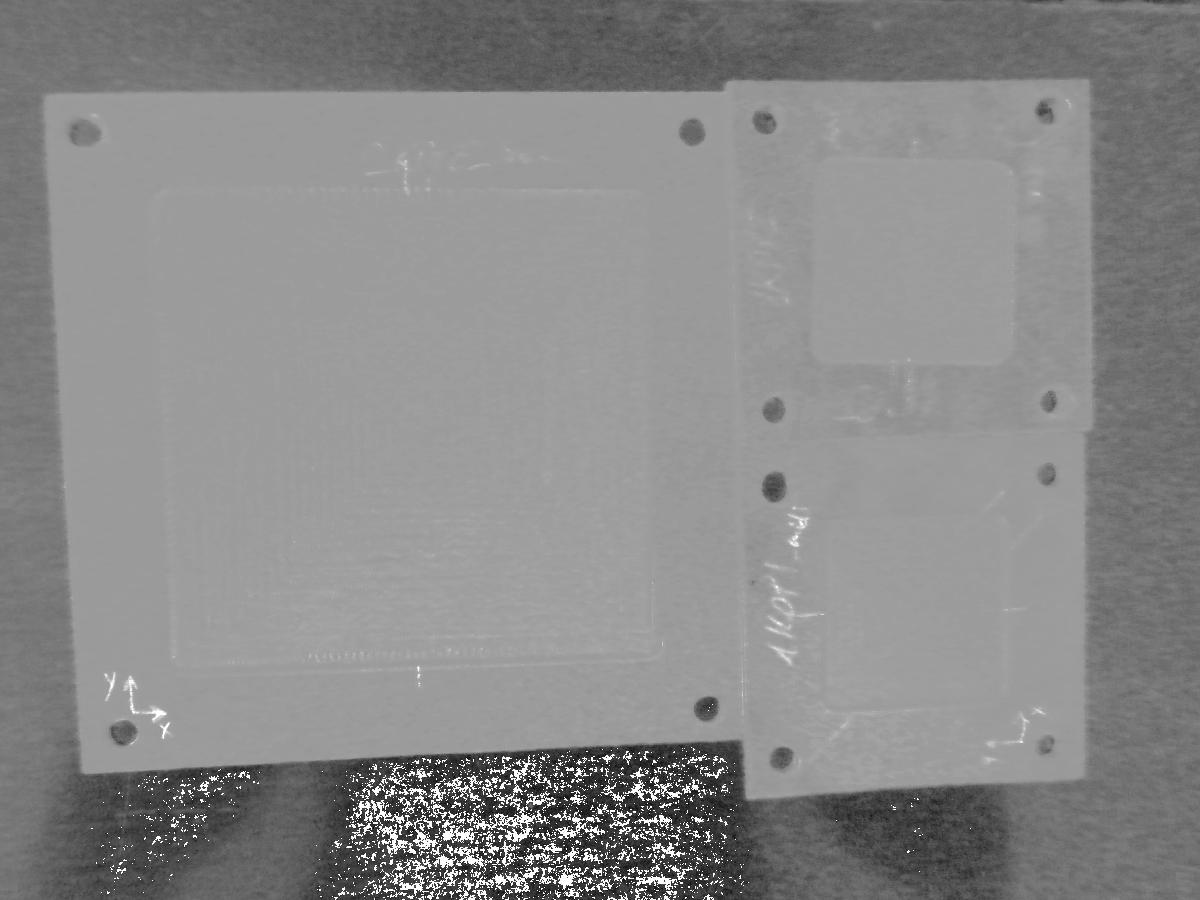

## References

- Upcroft, B., McManus, C., Churchill, W., Maddern, W., & Newman, P. "Lighting invariant urban street classification," *IEEE International Conference on Robotics and Automation (ICRA)*, pp. 1712-1718, 2014.

- Ratnasingam, S., & Collins, S. (2010). Study of the photodetector characteristics of a camera for color constancy in natural scenes. *Journal of the Optical Society of America A*, 27(2), 233-240.

- Ratnasingam, S., & McGinnity, T. M. (2012). Chromaticity space for illuminant invariant recognition. *IEEE Transactions on Image Processing*, 21(8), 3612-3623.